clc, clear all;


l = 1;
gamma = 0.01;
T = 50;

%Зададим разбиение
N = 101;
M = 1000;

x = linspace(0,l,N);
tau = linspace(0,T, M);

%Зададим краевые условия 
yLeft = zeros(1,M);
yRight = zeros(1,M);

for i = 1:M
    yLeft(i) = 1;
    yRight(i) = 1;

    %%
    %% Another code
    %%
end

%Зададим начальное условие
yNach = zeros(1,N);

for i = 1:N
    yNach(i) = - x(i)^2 + x(i) + 1;
end

%Правая часть
phi = zeros(N,M);

%%Some code

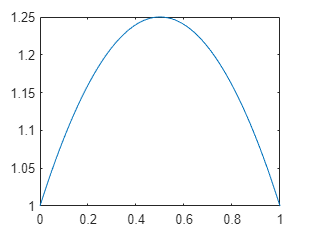

%График системы в начальном состоянии
plot(x,yNach);

result = UnExplicitSchemaForRealProblem(N, M, l, T, gamma, yRight,yLeft, yNach,  phi);

%График решения
plot(x,result);